%Построение полярной номограммы в системе Matlab
alfa=10;
fi=30;

a=deg2rad(alfa);
fi=deg2rad(fi);

for i=0:36
    

            

    b(i+1)=pi+i*pi/18;

            

    Ko(i+1)=abs(cos(a)/sin(a+b(i+1)));    

             

    Kv(i+1)=abs(sin(a+fi)/cos(a+b(i+1)+fi)); 

            

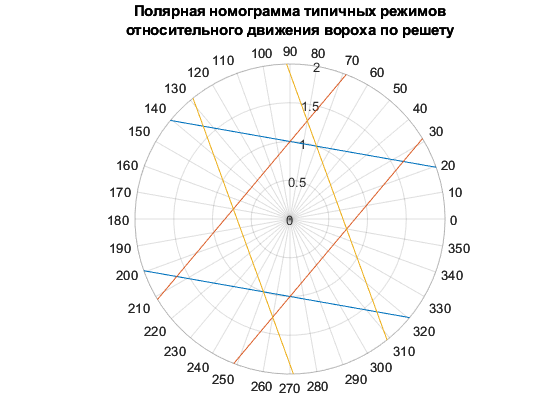

    Kn(i+1)=abs(sin(a+fi)/cos(a+b(i+1)-fi));
end
b; Ko; Kv; Kn;

%Построение графика в полярной системе координат
polarplot(b, Ko);
title({'Полярная номограмма типичных режимов'; 'относительного движения вороха по решету'});
thetaticks(0:10:360);
hold on;
polarplot(b, Kv);
polarplot(b, Kn);
hold off;
rlim([0 2]);